# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 09-Aug-2021 22:03:44

## Load the Pretrained Parameters

params = load("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\params_2021_08_09__22_03_34.mat");

## **Import Data**

Imort the art dataset to train and validate for claasification their artists.

art_image_dataset = imageDatastore("C:\Users\12424\Desktop\Acadimic\Computer Science\Master 1\Research Methodology Computer Science\Project\Dataset\BestArtAllTime\","IncludeSubfolders",true,"LabelSource","foldernames");
[art_image_Train, art_image_Validate] = splitEachLabel(art_image_dataset, 0.7, 'randomized');

Resize the image from dataset to a better match format for googleNet model.

resized_art_Train = augmentedImageDatastore([224 224 3], art_image_Train,"ColorPreprocessing","gray2rgb");
resized_art_Validate = augmentedImageDatastore([224 224 3],art_image_Validate,"ColorPreprocessing","gray2rgb");

## Set Training Options

Define the options for training the dataset.

options = trainingOptions("sgdm", ...
    "ExecutionEnvironment","gpu", ...
    "InitialLearnRate", 0.01, ...
    "LearnRateDropPeriod", 5, ...
    "MaxEpochs", 50, ...
    "MiniBatchSize", 10, ...
    "Momentum", 0.0, ...
    "Shuffle", "every-epoch", ...
    "ValidationFrequency", 4000, ...
    "Plots","training-progress", ...
    "ValidationData", resized_art_Validate)

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0
            InitialLearnRate: 0.0100
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 5
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 50
               MiniBatchSize: 10
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 4000
          ValidationPatience: Inf
                     Shuffle: 'every-epoch'
              CheckpointPath: ''
        ExecutionEnvironment: 'gpu'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePad

## Create Array of Layers

layers = [
    imageInputLayer([224 224 3],"Name","input","Mean",params.input.Mean)
    convolution2dLayer([3 3],64,"Name","conv1_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv1_1.Bias,"Weights",params.conv1_1.Weights)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],64,"Name","conv1_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv1_2.Bias,"Weights",params.conv1_2.Weights)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","conv2_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv2_1.Bias,"Weights",params.conv2_1.Weights)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],128,"Name","conv2_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv2_2.Bias,"Weights",params.conv2_2.Weights)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","conv3_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_1.Bias,"Weights",params.conv3_1.Weights)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],256,"Name","conv3_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_2.Bias,"Weights",params.conv3_2.Weights)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],256,"Name","conv3_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_3.Bias,"Weights",params.conv3_3.Weights)
    reluLayer("Name","relu3_3")
    convolution2dLayer([3 3],256,"Name","conv3_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv3_4.Bias,"Weights",params.conv3_4.Weights)
    reluLayer("Name","relu3_4")
    maxPooling2dLayer([2 2],"Name","pool3","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv4_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_1.Bias,"Weights",params.conv4_1.Weights)
    reluLayer("Name","relu4_1")
    convolution2dLayer([3 3],512,"Name","conv4_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_2.Bias,"Weights",params.conv4_2.Weights)
    reluLayer("Name","relu4_2")
    convolution2dLayer([3 3],512,"Name","conv4_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_3.Bias,"Weights",params.conv4_3.Weights)
    reluLayer("Name","relu4_3")
    convolution2dLayer([3 3],512,"Name","conv4_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv4_4.Bias,"Weights",params.conv4_4.Weights)
    reluLayer("Name","relu4_4")
    maxPooling2dLayer([2 2],"Name","pool4","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","conv5_1","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_1.Bias,"Weights",params.conv5_1.Weights)
    reluLayer("Name","relu5_1")
    convolution2dLayer([3 3],512,"Name","conv5_2","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_2.Bias,"Weights",params.conv5_2.Weights)
    reluLayer("Name","relu5_2")
    convolution2dLayer([3 3],512,"Name","conv5_3","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_3.Bias,"Weights",params.conv5_3.Weights)
    reluLayer("Name","relu5_3")
    convolution2dLayer([3 3],512,"Name","conv5_4","Padding",[1 1 1 1],"WeightL2Factor",0,"Bias",params.conv5_4.Bias,"Weights",params.conv5_4.Weights)
    reluLayer("Name","relu5_4")
    maxPooling2dLayer([2 2],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","WeightL2Factor",0,"Bias",params.fc6.Bias,"Weights",params.fc6.Weights)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","WeightL2Factor",0,"Bias",params.fc7.Bias,"Weights",params.fc7.Weights)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(51,"Name","fc","WeightL2Factor",0)
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Plot Layers

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:35 |        0.00% |        2.05% |       4.2610 |       4.1324 |          0.0100 |


|       1 |          50 |       00:00:45 |       20.00% |              |       3.3623 |              |          0.0100 |


|       1 |         100 |       00:00:56 |       10.00% |              |       3.7066 |              |          0.0100 |


|       1 |         150 |       00:01:06 |        0.00% |              |       3.4018 |              |          0.0100 |


|       1 |         200 |       00:01:17 |        0.00% |              |       3.6293 |              |          0.0100 |


|       1 |         250 |       00:01:28 |       20.00% |              |       3.1452 |              |          0.0100 |


|       1 |         300 |       00:01:39 |       10.00% |              |       3.8398 |              |          0.0100 |


|       1 |         350 |       00:01:50 |       10.00% |              |       3.1984 |              |          0.0100 |


|       1 |         400 |       00:02:02 |        0.00% |              |       3.4671 |              |          0.0100 |


|       1 |         450 |       00:02:13 |       10.00% |              |       3.5581 |              |          0.0100 |


|       1 |         500 |       00:02:25 |       10.00% |              |       3.6937 |              |          0.0100 |


|       1 |         550 |       00:02:36 |       10.00% |              |       3.4567 |              |          0.0100 |


|       1 |         600 |       00:02:48 |       30.00% |              |       2.9132 |              |          0.0100 |


|       2 |         650 |       00:03:00 |       20.00% |              |       3.0550 |              |          0.0100 |


|       2 |         700 |       00:03:11 |       20.00% |              |       3.7400 |              |          0.0100 |


|       2 |         750 |       00:03:22 |       40.00% |              |       3.1110 |              |          0.0100 |


|       2 |         800 |       00:03:34 |        0.00% |              |       3.7010 |              |          0.0100 |


|       2 |         850 |       00:03:46 |       40.00% |              |       2.9048 |              |          0.0100 |


|       2 |         900 |       00:03:58 |       30.00% |              |       2.8815 |              |          0.0100 |


|       2 |         950 |       00:04:09 |       20.00% |              |       3.1215 |              |          0.0100 |


|       2 |        1000 |       00:04:21 |       30.00% |              |       2.9076 |              |          0.0100 |


|       2 |        1050 |       00:04:33 |       20.00% |              |       3.2494 |              |          0.0100 |


|       2 |        1100 |       00:04:44 |       20.00% |              |       2.9634 |              |          0.0100 |


|       2 |        1150 |       00:04:56 |       20.00% |              |       3.2077 |              |          0.0100 |


|       2 |        1200 |       00:05:07 |       10.00% |              |       3.3094 |              |          0.0100 |


|       3 |        1250 |       00:05:19 |       20.00% |              |       2.8494 |              |          0.0100 |


|       3 |        1300 |       00:05:31 |        0.00% |              |       3.6610 |              |          0.0100 |


|       3 |        1350 |       00:05:42 |       20.00% |              |       2.7944 |              |          0.0100 |


|       3 |        1400 |       00:05:54 |       10.00% |              |       4.0329 |              |          0.0100 |


|       3 |        1450 |       00:06:06 |       30.00% |              |       2.8587 |              |          0.0100 |


|       3 |        1500 |       00:06:18 |       10.00% |              |       3.1089 |              |          0.0100 |


|       3 |        1550 |       00:06:29 |       10.00% |              |       3.0949 |              |          0.0100 |


|       3 |        1600 |       00:06:41 |        0.00% |              |       3.3817 |              |          0.0100 |


|       3 |        1650 |       00:06:53 |       20.00% |              |       3.1461 |              |          0.0100 |


|       3 |        1700 |       00:07:05 |       40.00% |              |       2.3293 |              |          0.0100 |


|       3 |        1750 |       00:07:16 |       10.00% |              |       3.1411 |              |          0.0100 |


|       3 |        1800 |       00:07:28 |       30.00% |              |       2.9995 |              |          0.0100 |


|       4 |        1850 |       00:07:41 |       30.00% |              |       2.1548 |              |          0.0100 |


|       4 |        1900 |       00:07:52 |       20.00% |              |       2.6806 |              |          0.0100 |


|       4 |        1950 |       00:08:04 |       10.00% |              |       3.4248 |              |          0.0100 |


|       4 |        2000 |       00:08:16 |       20.00% |              |       3.0606 |              |          0.0100 |


|       4 |        2050 |       00:08:28 |       30.00% |              |       2.5981 |              |          0.0100 |


|       4 |        2100 |       00:08:40 |       20.00% |              |       3.2929 |              |          0.0100 |


|       4 |        2150 |       00:08:51 |       10.00% |              |       3.1201 |              |          0.0100 |


|       4 |        2200 |       00:09:03 |       30.00% |              |       2.7427 |              |          0.0100 |


|       4 |        2250 |       00:09:15 |       30.00% |              |       2.5031 |              |          0.0100 |


|       4 |        2300 |       00:09:27 |        0.00% |              |       3.5256 |              |          0.0100 |


|       4 |        2350 |       00:09:38 |       10.00% |              |       3.5686 |              |          0.0100 |


|       4 |        2400 |       00:09:50 |       30.00% |              |       2.5798 |              |          0.0100 |


|       4 |        2450 |       00:10:02 |       30.00% |              |       2.9017 |              |          0.0100 |


|       5 |        2500 |       00:10:14 |        0.00% |              |       3.6464 |              |          0.0100 |


|       5 |        2550 |       00:10:25 |       20.00% |              |       2.7810 |              |          0.0100 |


|       5 |        2600 |       00:10:37 |       10.00% |              |       3.3141 |              |          0.0100 |


|       5 |        2650 |       00:10:49 |       30.00% |              |       2.9518 |              |          0.0100 |


|       5 |        2700 |       00:11:01 |       20.00% |              |       2.6269 |              |          0.0100 |


|       5 |        2750 |       00:11:13 |       10.00% |              |       2.9891 |              |          0.0100 |


|       5 |        2800 |       00:11:25 |       20.00% |              |       2.8010 |              |          0.0100 |


|       5 |        2850 |       00:11:37 |       20.00% |              |       2.5276 |              |          0.0100 |


|       5 |        2900 |       00:11:49 |       30.00% |              |       2.8090 |              |          0.0100 |


|       5 |        2950 |       00:12:01 |       10.00% |              |       3.0533 |              |          0.0100 |


|       5 |        3000 |       00:12:13 |       20.00% |              |       2.6924 |              |          0.0100 |


|       5 |        3050 |       00:12:25 |        0.00% |              |       2.6808 |              |          0.0100 |


|       6 |        3100 |       00:12:36 |       20.00% |              |       2.3599 |              |          0.0100 |


|       6 |        3150 |       00:12:48 |       20.00% |              |       3.0300 |              |          0.0100 |


|       6 |        3200 |       00:13:00 |       40.00% |              |       2.8724 |              |          0.0100 |


|       6 |        3250 |       00:13:12 |       30.00% |              |       3.3091 |              |          0.0100 |


|       6 |        3300 |       00:13:24 |       10.00% |              |       3.0295 |              |          0.0100 |


|       6 |        3350 |       00:13:36 |       20.00% |              |       3.1604 |              |          0.0100 |


|       6 |        3400 |       00:13:48 |       10.00% |              |       3.0455 |              |          0.0100 |


|       6 |        3450 |       00:13:59 |        0.00% |              |       3.3720 |              |          0.0100 |


|       6 |        3500 |       00:14:11 |       40.00% |              |       2.4723 |              |          0.0100 |


|       6 |        3550 |       00:14:23 |       20.00% |              |       3.0647 |              |          0.0100 |


|       6 |        3600 |       00:14:36 |       40.00% |              |       2.4467 |              |          0.0100 |


|       6 |        3650 |       00:14:47 |       10.00% |              |       3.0161 |              |          0.0100 |


|       7 |        3700 |       00:15:00 |       20.00% |              |       2.8432 |              |          0.0100 |


|       7 |        3750 |       00:15:12 |       20.00% |              |       2.8280 |              |          0.0100 |


|       7 |        3800 |       00:15:24 |       30.00% |              |       2.5520 |              |          0.0100 |


|       7 |        3850 |       00:15:36 |       30.00% |              |       2.1436 |              |          0.0100 |


|       7 |        3900 |       00:15:48 |       40.00% |              |       2.3393 |              |          0.0100 |


|       7 |        3950 |       00:16:00 |       10.00% |              |       2.9164 |              |          0.0100 |


|       7 |        4000 |       00:16:50 |       30.00% |       25.10% |       2.1827 |       2.6871 |          0.0100 |


|       7 |        4050 |       00:17:01 |       30.00% |              |       3.2496 |              |          0.0100 |


|       7 |        4100 |       00:17:13 |       20.00% |              |       2.7902 |              |          0.0100 |


|       7 |        4150 |       00:17:24 |       10.00% |              |       3.0397 |              |          0.0100 |


|       7 |        4200 |       00:17:36 |       40.00% |              |       2.5669 |              |          0.0100 |


|       7 |        4250 |       00:17:48 |       20.00% |              |       2.1830 |              |          0.0100 |


|       8 |        4300 |       00:18:00 |       30.00% |              |       2.1708 |              |          0.0100 |


|       8 |        4350 |       00:18:11 |       20.00% |              |       2.6043 |              |          0.0100 |


|       8 |        4400 |       00:18:23 |       10.00% |              |       2.5454 |              |          0.0100 |


|       8 |        4450 |       00:18:35 |       20.00% |              |       2.9986 |              |          0.0100 |


|       8 |        4500 |       00:18:48 |       10.00% |              |       3.2507 |              |          0.0100 |


|       8 |        4550 |       00:19:00 |       20.00% |              |       2.7925 |              |          0.0100 |


|       8 |        4600 |       00:19:12 |       20.00% |              |       3.0509 |              |          0.0100 |


|       8 |        4650 |       00:19:24 |       50.00% |              |       1.8753 |              |          0.0100 |


|       8 |        4700 |       00:19:36 |       50.00% |              |       2.2414 |              |          0.0100 |


|       8 |        4750 |       00:19:48 |       30.00% |              |       2.3258 |              |          0.0100 |


|       8 |        4800 |       00:20:00 |       30.00% |              |       2.6980 |              |          0.0100 |


|       8 |        4850 |       00:20:12 |       40.00% |              |       2.4698 |              |          0.0100 |


|       8 |        4900 |       00:20:24 |       20.00% |              |       3.7637 |              |          0.0100 |


|       9 |        4950 |       00:20:36 |       10.00% |              |       3.8980 |              |          0.0100 |


|       9 |        5000 |       00:20:49 |       50.00% |              |       2.0518 |              |          0.0100 |


|       9 |        5050 |       00:21:01 |       40.00% |              |       2.3039 |              |          0.0100 |


|       9 |        5100 |       00:21:13 |       10.00% |              |       3.2161 |              |          0.0100 |


|       9 |        5150 |       00:21:26 |       50.00% |              |       2.6072 |              |          0.0100 |


|       9 |        5200 |       00:21:37 |       20.00% |              |       2.7186 |              |          0.0100 |


|       9 |        5250 |       00:21:50 |       40.00% |              |       2.3145 |              |          0.0100 |


|       9 |        5300 |       00:22:02 |       40.00% |              |       2.1630 |              |          0.0100 |


|       9 |        5350 |       00:22:14 |       50.00% |              |       2.3635 |              |          0.0100 |


|       9 |        5400 |       00:22:26 |       40.00% |              |       1.9462 |              |          0.0100 |


|       9 |        5450 |       00:22:38 |       30.00% |              |       2.2231 |              |          0.0100 |


|       9 |        5500 |       00:22:50 |       20.00% |              |       3.0894 |              |          0.0100 |


|      10 |        5550 |       00:23:02 |       50.00% |              |       1.7373 |              |          0.0100 |


|      10 |        5600 |       00:23:14 |       20.00% |              |       2.9992 |              |          0.0100 |


|      10 |        5650 |       00:23:26 |       20.00% |              |       2.5057 |              |          0.0100 |


|      10 |        5700 |       00:23:38 |       40.00% |              |       1.6104 |              |          0.0100 |


|      10 |        5750 |       00:23:50 |       10.00% |              |       2.6938 |              |          0.0100 |


|      10 |        5800 |       00:24:03 |       20.00% |              |       2.9478 |              |          0.0100 |


|      10 |        5850 |       00:24:15 |       10.00% |              |       2.9133 |              |          0.0100 |


|      10 |        5900 |       00:24:27 |       20.00% |              |       2.8979 |              |          0.0100 |


|      10 |        5950 |       00:24:39 |       30.00% |              |       2.3515 |              |          0.0100 |


|      10 |        6000 |       00:24:51 |       30.00% |              |       3.2424 |              |          0.0100 |


|      10 |        6050 |       00:25:03 |       30.00% |              |       2.8353 |              |          0.0100 |


|      10 |        6100 |       00:25:15 |       20.00% |              |       2.4320 |              |          0.0100 |


|      11 |        6150 |       00:25:28 |       40.00% |              |       2.2249 |              |          0.0100 |


|      11 |        6200 |       00:25:40 |       40.00% |              |       2.2776 |              |          0.0100 |


|      11 |        6250 |       00:25:52 |       30.00% |              |       2.8231 |              |          0.0100 |


|      11 |        6300 |       00:26:04 |       30.00% |              |       2.0170 |              |          0.0100 |


|      11 |        6350 |       00:26:16 |       20.00% |              |       2.3125 |              |          0.0100 |


|      11 |        6400 |       00:26:28 |       40.00% |              |       2.5544 |              |          0.0100 |


|      11 |        6450 |       00:26:40 |       40.00% |              |       2.6381 |              |          0.0100 |


|      11 |        6500 |       00:26:52 |       50.00% |              |       1.7768 |              |          0.0100 |


|      11 |        6550 |       00:27:04 |       40.00% |              |       2.4271 |              |          0.0100 |


|      11 |        6600 |       00:27:15 |       30.00% |              |       2.3996 |              |          0.0100 |


|      11 |        6650 |       00:27:27 |       40.00% |              |       1.9960 |              |          0.0100 |


|      11 |        6700 |       00:27:39 |       50.00% |              |       2.4078 |              |          0.0100 |


|      11 |        6750 |       00:27:51 |       30.00% |              |       2.8004 |              |          0.0100 |


|      12 |        6800 |       00:28:03 |       40.00% |              |       1.7975 |              |          0.0100 |


|      12 |        6850 |       00:28:15 |       40.00% |              |       2.1825 |              |          0.0100 |


|      12 |        6900 |       00:28:27 |       40.00% |              |       2.3902 |              |          0.0100 |


|      12 |        6950 |       00:28:39 |       50.00% |              |       2.2346 |              |          0.0100 |


|      12 |        7000 |       00:28:51 |       20.00% |              |       2.5503 |              |          0.0100 |


|      12 |        7050 |       00:29:03 |       20.00% |              |       2.8952 |              |          0.0100 |


|      12 |        7100 |       00:29:15 |       40.00% |              |       2.2834 |              |          0.0100 |


|      12 |        7150 |       00:29:26 |       20.00% |              |       3.0411 |              |          0.0100 |


|      12 |        7200 |       00:29:38 |       60.00% |              |       2.3635 |              |          0.0100 |


|      12 |        7250 |       00:29:50 |       30.00% |              |       1.7495 |              |          0.0100 |


|      12 |        7300 |       00:30:02 |       40.00% |              |       2.4890 |              |          0.0100 |


|      12 |        7350 |       00:30:14 |       20.00% |              |       2.7931 |              |          0.0100 |


|      13 |        7400 |       00:30:26 |       40.00% |              |       1.6858 |              |          0.0100 |


|      13 |        7450 |       00:30:38 |       40.00% |              |       2.1454 |              |          0.0100 |


|      13 |        7500 |       00:30:50 |       20.00% |              |       2.7670 |              |          0.0100 |


|      13 |        7550 |       00:31:02 |       30.00% |              |       2.5370 |              |          0.0100 |


|      13 |        7600 |       00:31:14 |       60.00% |              |       1.7475 |              |          0.0100 |


|      13 |        7650 |       00:31:26 |       20.00% |              |       2.4617 |              |          0.0100 |


|      13 |        7700 |       00:31:37 |       30.00% |              |       2.5641 |              |          0.0100 |


|      13 |        7750 |       00:31:49 |       20.00% |              |       2.4553 |              |          0.0100 |


|      13 |        7800 |       00:32:01 |       30.00% |              |       2.8969 |              |          0.0100 |


|      13 |        7850 |       00:32:13 |       20.00% |              |       2.9975 |              |          0.0100 |


|      13 |        7900 |       00:32:25 |       30.00% |              |       2.3618 |              |          0.0100 |


|      13 |        7950 |       00:32:37 |       10.00% |              |       2.1518 |              |          0.0100 |


|      14 |        8000 |       00:33:26 |       50.00% |       33.12% |       1.7886 |       2.4114 |          0.0100 |


|      14 |        8050 |       00:33:38 |       40.00% |              |       1.8934 |              |          0.0100 |


|      14 |        8100 |       00:33:50 |       40.00% |              |       2.2693 |              |          0.0100 |


|      14 |        8150 |       00:34:01 |       50.00% |              |       2.2321 |              |          0.0100 |


|      14 |        8200 |       00:34:13 |       70.00% |              |       1.4631 |              |          0.0100 |


|      14 |        8250 |       00:34:24 |       20.00% |              |       2.4790 |              |          0.0100 |


|      14 |        8300 |       00:34:37 |       10.00% |              |       3.0377 |              |          0.0100 |


|      14 |        8350 |       00:34:49 |       30.00% |              |       1.9981 |              |          0.0100 |


|      14 |        8400 |       00:35:00 |       40.00% |              |       2.2436 |              |          0.0100 |


|      14 |        8450 |       00:35:12 |       50.00% |              |       2.1581 |              |          0.0100 |


|      14 |        8500 |       00:35:24 |       10.00% |              |       3.2723 |              |          0.0100 |


|      14 |        8550 |       00:35:36 |       30.00% |              |       2.9506 |              |          0.0100 |


|      15 |        8600 |       00:35:48 |       70.00% |              |       1.7579 |              |          0.0100 |


|      15 |        8650 |       00:36:00 |       50.00% |              |       1.8174 |              |          0.0100 |


|      15 |        8700 |       00:36:12 |       10.00% |              |       2.2631 |              |          0.0100 |


|      15 |        8750 |       00:36:24 |       40.00% |              |       2.0366 |              |          0.0100 |


|      15 |        8800 |       00:36:36 |       50.00% |              |       2.0878 |              |          0.0100 |


|      15 |        8850 |       00:36:48 |       10.00% |              |       2.7187 |              |          0.0100 |


|      15 |        8900 |       00:37:00 |       60.00% |              |       1.6959 |              |          0.0100 |


|      15 |        8950 |       00:37:12 |       20.00% |              |       2.3365 |              |          0.0100 |


|      15 |        9000 |       00:37:24 |       70.00% |              |       1.1007 |              |          0.0100 |


|      15 |        9050 |       00:37:36 |       30.00% |              |       1.9610 |              |          0.0100 |


|      15 |        9100 |       00:37:49 |       40.00% |              |       2.3810 |              |          0.0100 |


|      15 |        9150 |       00:38:01 |       30.00% |              |       2.5920 |              |          0.0100 |


|      15 |        9200 |       00:38:13 |       30.00% |              |       2.7317 |              |          0.0100 |


|      16 |        9250 |       00:38:25 |       30.00% |              |       2.1180 |              |          0.0100 |


|      16 |        9300 |       00:38:37 |       30.00% |              |       2.1385 |              |          0.0100 |


|      16 |        9350 |       00:38:49 |       50.00% |              |       2.0019 |              |          0.0100 |


|      16 |        9400 |       00:39:01 |       30.00% |              |       2.7327 |              |          0.0100 |


|      16 |        9450 |       00:39:13 |       40.00% |              |       2.3114 |              |          0.0100 |


|      16 |        9500 |       00:39:25 |       40.00% |              |       2.2511 |              |          0.0100 |


|      16 |        9550 |       00:39:37 |       20.00% |              |       2.6356 |              |          0.0100 |


|      16 |        9600 |       00:39:49 |       40.00% |              |       1.7909 |              |          0.0100 |


|      16 |        9650 |       00:40:01 |       30.00% |              |       3.0033 |              |          0.0100 |


|      16 |        9700 |       00:40:12 |       40.00% |              |       2.2985 |              |          0.0100 |


|      16 |        9750 |       00:40:25 |       40.00% |              |       2.0604 |              |          0.0100 |


|      16 |        9800 |       00:40:37 |       50.00% |              |       2.2493 |              |          0.0100 |


|      17 |        9850 |       00:40:49 |       50.00% |              |       1.7768 |              |          0.0100 |


|      17 |        9900 |       00:41:01 |       40.00% |              |       1.5569 |              |          0.0100 |


|      17 |        9950 |       00:41:13 |       10.00% |              |       2.7465 |              |          0.0100 |


|      17 |       10000 |       00:41:25 |       30.00% |              |       2.8012 |              |          0.0100 |


|      17 |       10050 |       00:41:37 |       50.00% |              |       2.1916 |              |          0.0100 |


|      17 |       10100 |       00:41:49 |       70.00% |              |       1.7595 |              |          0.0100 |


|      17 |       10150 |       00:42:01 |       40.00% |              |       1.7831 |              |          0.0100 |


|      17 |       10200 |       00:42:13 |       50.00% |              |       1.8713 |              |          0.0100 |


|      17 |       10250 |       00:42:25 |       10.00% |              |       2.3151 |              |          0.0100 |


|      17 |       10300 |       00:42:37 |       30.00% |              |       2.0181 |              |          0.0100 |


|      17 |       10350 |       00:42:49 |       60.00% |              |       1.9345 |              |          0.0100 |


|      17 |       10400 |       00:43:02 |       50.00% |              |       1.9733 |              |          0.0100 |


|      18 |       10450 |       00:43:14 |       50.00% |              |       1.5746 |              |          0.0100 |


|      18 |       10500 |       00:43:26 |       20.00% |              |       2.7714 |              |          0.0100 |


|      18 |       10550 |       00:43:38 |       40.00% |              |       1.8922 |              |          0.0100 |


|      18 |       10600 |       00:43:50 |       10.00% |              |       2.6804 |              |          0.0100 |


|      18 |       10650 |       00:44:02 |       10.00% |              |       2.4786 |              |          0.0100 |


|      18 |       10700 |       00:44:14 |       40.00% |              |       1.5928 |              |          0.0100 |


|      18 |       10750 |       00:44:26 |       20.00% |              |       2.7829 |              |          0.0100 |


|      18 |       10800 |       00:44:38 |       20.00% |              |       2.1241 |              |          0.0100 |


|      18 |       10850 |       00:44:50 |       10.00% |              |       2.5872 |              |          0.0100 |


|      18 |       10900 |       00:45:02 |       40.00% |              |       2.2999 |              |          0.0100 |


|      18 |       10950 |       00:45:14 |       20.00% |              |       2.5960 |              |          0.0100 |


|      18 |       11000 |       00:45:26 |       50.00% |              |       1.7960 |              |          0.0100 |


|      18 |       11050 |       00:45:38 |       30.00% |              |       2.0709 |              |          0.0100 |


|      19 |       11100 |       00:45:50 |       10.00% |              |       3.8414 |              |          0.0100 |


|      19 |       11150 |       00:46:03 |       10.00% |              |       2.6609 |              |          0.0100 |


|      19 |       11200 |       00:46:15 |       10.00% |              |       3.2803 |              |          0.0100 |


|      19 |       11250 |       00:46:27 |       50.00% |              |       1.6852 |              |          0.0100 |


|      19 |       11300 |       00:46:39 |       30.00% |              |       1.8853 |              |          0.0100 |


|      19 |       11350 |       00:46:52 |       80.00% |              |       1.2259 |              |          0.0100 |


|      19 |       11400 |       00:47:04 |       50.00% |              |       2.2793 |              |          0.0100 |


|      19 |       11450 |       00:47:15 |       70.00% |              |       1.3318 |              |          0.0100 |


|      19 |       11500 |       00:47:28 |       60.00% |              |       1.7934 |              |          0.0100 |


|      19 |       11550 |       00:47:40 |       40.00% |              |       1.6336 |              |          0.0100 |


|      19 |       11600 |       00:47:52 |       20.00% |              |       2.3099 |              |          0.0100 |


|      19 |       11650 |       00:48:05 |       50.00% |              |       2.0287 |              |          0.0100 |


|      20 |       11700 |       00:48:17 |       50.00% |              |       1.6106 |              |          0.0100 |


|      20 |       11750 |       00:48:29 |       60.00% |              |       1.3852 |              |          0.0100 |


|      20 |       11800 |       00:48:41 |       50.00% |              |       2.1394 |              |          0.0100 |


|      20 |       11850 |       00:48:54 |       20.00% |              |       1.7070 |              |          0.0100 |


|      20 |       11900 |       00:49:06 |       30.00% |              |       1.8062 |              |          0.0100 |


|      20 |       11950 |       00:49:18 |       40.00% |              |       1.9234 |              |          0.0100 |


|      20 |       12000 |       00:50:08 |       20.00% |       32.09% |       2.4337 |       2.3782 |          0.0100 |


|      20 |       12050 |       00:50:20 |       30.00% |              |       1.6928 |              |          0.0100 |


|      20 |       12100 |       00:50:32 |       30.00% |              |       2.6219 |              |          0.0100 |


|      20 |       12150 |       00:50:44 |       20.00% |              |       2.9146 |              |          0.0100 |


|      20 |       12200 |       00:50:56 |       50.00% |              |       1.9564 |              |          0.0100 |


|      20 |       12250 |       00:51:08 |       30.00% |              |       1.9380 |              |          0.0100 |


|      21 |       12300 |       00:51:20 |       80.00% |              |       1.5599 |              |          0.0100 |


|      21 |       12350 |       00:51:33 |       60.00% |              |       1.4606 |              |          0.0100 |


|      21 |       12400 |       00:51:45 |       70.00% |              |       1.0673 |              |          0.0100 |


|      21 |       12450 |       00:51:58 |       60.00% |              |       1.1887 |              |          0.0100 |


|      21 |       12500 |       00:52:10 |       10.00% |              |       2.7425 |              |          0.0100 |


|      21 |       12550 |       00:52:22 |       70.00% |              |       1.1204 |              |          0.0100 |


|      21 |       12600 |       00:52:35 |       40.00% |              |       2.1268 |              |          0.0100 |


|      21 |       12650 |       00:52:47 |       20.00% |              |       2.0403 |              |          0.0100 |


|      21 |       12700 |       00:52:59 |       30.00% |              |       2.6233 |              |          0.0100 |


|      21 |       12750 |       00:53:12 |       30.00% |              |       1.8699 |              |          0.0100 |


|      21 |       12800 |       00:53:24 |       40.00% |              |       1.8243 |              |          0.0100 |


|      21 |       12850 |       00:53:36 |       50.00% |              |       2.1462 |              |          0.0100 |


|      22 |       12900 |       00:53:48 |       60.00% |              |       1.6743 |              |          0.0100 |


|      22 |       12950 |       00:54:00 |       60.00% |              |       1.8898 |              |          0.0100 |


|      22 |       13000 |       00:54:12 |       30.00% |              |       2.2656 |              |          0.0100 |


|      22 |       13050 |       00:54:24 |       50.00% |              |       1.5526 |              |          0.0100 |


|      22 |       13100 |       00:54:36 |       40.00% |              |       2.2174 |              |          0.0100 |


|      22 |       13150 |       00:54:48 |       60.00% |              |       1.5343 |              |          0.0100 |


|      22 |       13200 |       00:55:01 |       60.00% |              |       0.8903 |              |          0.0100 |


|      22 |       13250 |       00:55:13 |       30.00% |              |       1.6524 |              |          0.0100 |


|      22 |       13300 |       00:55:25 |       20.00% |              |       2.5299 |              |          0.0100 |


|      22 |       13350 |       00:55:37 |       30.00% |              |       2.1075 |              |          0.0100 |


|      22 |       13400 |       00:55:50 |       30.00% |              |       1.2628 |              |          0.0100 |


|      22 |       13450 |       00:56:02 |       30.00% |              |       1.6641 |              |          0.0100 |


|      22 |       13500 |       00:56:14 |       30.00% |              |       2.0537 |              |          0.0100 |


|      23 |       13550 |       00:56:27 |       70.00% |              |       1.3334 |              |          0.0100 |


|      23 |       13600 |       00:56:39 |       40.00% |              |       2.2987 |              |          0.0100 |


|      23 |       13650 |       00:56:51 |       50.00% |              |       1.3755 |              |          0.0100 |


|      23 |       13700 |       00:57:04 |       50.00% |              |       1.4203 |              |          0.0100 |


|      23 |       13750 |       00:57:16 |       20.00% |              |       2.1991 |              |          0.0100 |


|      23 |       13800 |       00:57:28 |       50.00% |              |       2.0069 |              |          0.0100 |


|      23 |       13850 |       00:57:40 |       60.00% |              |       1.6477 |              |          0.0100 |


|      23 |       13900 |       00:57:53 |       50.00% |              |       1.5391 |              |          0.0100 |


|      23 |       13950 |       00:58:05 |       40.00% |              |       1.6221 |              |          0.0100 |


|      23 |       14000 |       00:58:18 |       40.00% |              |       1.6663 |              |          0.0100 |


|      23 |       14050 |       00:58:30 |       10.00% |              |       2.1588 |              |          0.0100 |


|      23 |       14100 |       00:58:42 |       50.00% |              |       1.4900 |              |          0.0100 |


|      24 |       14150 |       00:58:54 |       30.00% |              |       2.2590 |              |          0.0100 |


|      24 |       14200 |       00:59:06 |       40.00% |              |       3.1072 |              |          0.0100 |


|      24 |       14250 |       00:59:19 |       40.00% |              |       1.6462 |              |          0.0100 |


|      24 |       14300 |       00:59:32 |       50.00% |              |       1.5171 |              |          0.0100 |


|      24 |       14350 |       00:59:44 |       10.00% |              |       2.9609 |              |          0.0100 |


|      24 |       14400 |       00:59:56 |       40.00% |              |       1.6363 |              |          0.0100 |


|      24 |       14450 |       01:00:08 |       30.00% |              |       2.0678 |              |          0.0100 |


|      24 |       14500 |       01:00:21 |       10.00% |              |       2.7205 |              |          0.0100 |


|      24 |       14550 |       01:00:33 |       20.00% |              |       2.1064 |              |          0.0100 |


|      24 |       14600 |       01:00:45 |       50.00% |              |       2.0311 |              |          0.0100 |


|      24 |       14650 |       01:00:57 |       70.00% |              |       1.3141 |              |          0.0100 |


|      24 |       14700 |       01:01:09 |       50.00% |              |       2.1318 |              |          0.0100 |


|      25 |       14750 |       01:01:21 |       70.00% |              |       1.4750 |              |          0.0100 |


|      25 |       14800 |       01:01:33 |       70.00% |              |       1.2386 |              |          0.0100 |


|      25 |       14850 |       01:01:45 |       40.00% |              |       1.8389 |              |          0.0100 |


|      25 |       14900 |       01:01:57 |       70.00% |              |       1.0649 |              |          0.0100 |


|      25 |       14950 |       01:02:10 |       30.00% |              |       2.7279 |              |          0.0100 |


|      25 |       15000 |       01:02:22 |       70.00% |              |       1.5637 |              |          0.0100 |


|      25 |       15050 |       01:02:34 |       50.00% |              |       2.2315 |              |          0.0100 |


|      25 |       15100 |       01:02:47 |       60.00% |              |       2.0528 |              |          0.0100 |


|      25 |       15150 |       01:02:59 |       50.00% |              |       1.4916 |              |          0.0100 |


|      25 |       15200 |       01:03:12 |       30.00% |              |       2.0663 |              |          0.0100 |


|      25 |       15250 |       01:03:24 |       40.00% |              |       1.7816 |              |          0.0100 |


|      25 |       15300 |       01:03:36 |       80.00% |              |       1.0727 |              |          0.0100 |


|      25 |       15350 |       01:03:48 |       40.00% |              |       1.8958 |              |          0.0100 |


|      26 |       15400 |       01:04:01 |       50.00% |              |       1.5354 |              |          0.0100 |


|      26 |       15450 |       01:04:14 |       40.00% |              |       1.3873 |              |          0.0100 |


|      26 |       15500 |       01:04:26 |       60.00% |              |       1.3285 |              |          0.0100 |


|      26 |       15550 |       01:04:39 |       60.00% |              |       1.6274 |              |          0.0100 |


|      26 |       15600 |       01:04:51 |       50.00% |              |       2.5077 |              |          0.0100 |


|      26 |       15650 |       01:05:03 |       40.00% |              |       1.6226 |              |          0.0100 |


|      26 |       15700 |       01:05:16 |       70.00% |              |       1.2469 |              |          0.0100 |


|      26 |       15750 |       01:05:28 |       40.00% |              |       2.1761 |              |          0.0100 |


|      26 |       15800 |       01:05:40 |       40.00% |              |       1.6583 |              |          0.0100 |


|      26 |       15850 |       01:05:52 |       40.00% |              |       1.8533 |              |          0.0100 |


|      26 |       15900 |       01:06:04 |       60.00% |              |       1.8390 |              |          0.0100 |


|      26 |       15950 |       01:06:16 |       50.00% |              |       1.4090 |              |          0.0100 |


|      27 |       16000 |       01:07:06 |       30.00% |       39.92% |       2.4656 |       2.2511 |          0.0100 |


|      27 |       16050 |       01:07:18 |       40.00% |              |       1.8725 |              |          0.0100 |


|      27 |       16100 |       01:07:30 |       30.00% |              |       2.1462 |              |          0.0100 |


|      27 |       16150 |       01:07:42 |       50.00% |              |       1.6927 |              |          0.0100 |


|      27 |       16200 |       01:07:54 |       10.00% |              |       2.4467 |              |          0.0100 |


|      27 |       16250 |       01:08:06 |       70.00% |              |       1.1125 |              |          0.0100 |


|      27 |       16300 |       01:08:18 |       40.00% |              |       1.5438 |              |          0.0100 |


|      27 |       16350 |       01:08:30 |       50.00% |              |       1.7066 |              |          0.0100 |


|      27 |       16400 |       01:08:42 |       40.00% |              |       1.4655 |              |          0.0100 |


|      27 |       16450 |       01:08:55 |       70.00% |              |       1.4007 |              |          0.0100 |


|      27 |       16500 |       01:09:07 |       60.00% |              |       1.6754 |              |          0.0100 |


|      27 |       16550 |       01:09:19 |       50.00% |              |       1.6077 |              |          0.0100 |


|      28 |       16600 |       01:09:31 |       70.00% |              |       1.1684 |              |          0.0100 |


|      28 |       16650 |       01:09:43 |       30.00% |              |       2.0139 |              |          0.0100 |


|      28 |       16700 |       01:09:55 |       70.00% |              |       1.4286 |              |          0.0100 |


|      28 |       16750 |       01:10:07 |       40.00% |              |       1.3226 |              |          0.0100 |


|      28 |       16800 |       01:10:19 |       40.00% |              |       1.7678 |              |          0.0100 |


|      28 |       16850 |       01:10:32 |       50.00% |              |       1.6154 |              |          0.0100 |


|      28 |       16900 |       01:10:44 |       80.00% |              |       0.9880 |              |          0.0100 |


|      28 |       16950 |       01:10:56 |       20.00% |              |       2.2182 |              |          0.0100 |


|      28 |       17000 |       01:11:08 |       50.00% |              |       0.9021 |              |          0.0100 |


|      28 |       17050 |       01:11:20 |       30.00% |              |       2.1913 |              |          0.0100 |


|      28 |       17100 |       01:11:33 |       70.00% |              |       1.7445 |              |          0.0100 |


|      28 |       17150 |       01:11:45 |       80.00% |              |       1.0434 |              |          0.0100 |


|      29 |       17200 |       01:11:57 |       60.00% |              |       1.1407 |              |          0.0100 |


|      29 |       17250 |       01:12:09 |       40.00% |              |       2.2183 |              |          0.0100 |


|      29 |       17300 |       01:12:22 |       30.00% |              |       2.0012 |              |          0.0100 |


|      29 |       17350 |       01:12:34 |       30.00% |              |       2.6775 |              |          0.0100 |


|      29 |       17400 |       01:12:46 |       50.00% |              |       1.6582 |              |          0.0100 |


|      29 |       17450 |       01:12:59 |       80.00% |              |       0.8458 |              |          0.0100 |


|      29 |       17500 |       01:13:11 |       40.00% |              |       1.8621 |              |          0.0100 |


|      29 |       17550 |       01:13:23 |       60.00% |              |       1.8153 |              |          0.0100 |


|      29 |       17600 |       01:13:36 |       20.00% |              |       2.2218 |              |          0.0100 |


|      29 |       17650 |       01:13:49 |       40.00% |              |       1.6039 |              |          0.0100 |


|      29 |       17700 |       01:14:02 |       60.00% |              |       1.9464 |              |          0.0100 |


|      29 |       17750 |       01:14:14 |       40.00% |              |       2.5216 |              |          0.0100 |


|      29 |       17800 |       01:14:26 |       60.00% |              |       1.5676 |              |          0.0100 |


|      30 |       17850 |       01:14:38 |       50.00% |              |       1.3469 |              |          0.0100 |


|      30 |       17900 |       01:14:51 |       40.00% |              |       1.2899 |              |          0.0100 |


|      30 |       17950 |       01:15:03 |       30.00% |              |       1.5998 |              |          0.0100 |


|      30 |       18000 |       01:15:15 |       40.00% |              |       1.8075 |              |          0.0100 |


|      30 |       18050 |       01:15:27 |       60.00% |              |       1.8300 |              |          0.0100 |


|      30 |       18100 |       01:15:39 |       30.00% |              |       2.0540 |              |          0.0100 |


|      30 |       18150 |       01:15:52 |       60.00% |              |       1.1404 |              |          0.0100 |


|      30 |       18200 |       01:16:04 |       80.00% |              |       1.4335 |              |          0.0100 |


|      30 |       18250 |       01:16:16 |       50.00% |              |       1.3851 |              |          0.0100 |


|      30 |       18300 |       01:16:29 |       40.00% |              |       1.2074 |              |          0.0100 |


|      30 |       18350 |       01:16:41 |       60.00% |              |       1.3381 |              |          0.0100 |


|      30 |       18400 |       01:16:53 |       30.00% |              |       1.8567 |              |          0.0100 |


|      31 |       18450 |       01:17:06 |       40.00% |              |       1.5371 |              |          0.0100 |


|      31 |       18500 |       01:17:18 |       90.00% |              |       0.8138 |              |          0.0100 |


|      31 |       18550 |       01:17:30 |       40.00% |              |       1.7555 |              |          0.0100 |


|      31 |       18600 |       01:17:42 |       70.00% |              |       1.2512 |              |          0.0100 |


|      31 |       18650 |       01:17:55 |       20.00% |              |       3.4682 |              |          0.0100 |


|      31 |       18700 |       01:18:07 |       50.00% |              |       2.0120 |              |          0.0100 |


|      31 |       18750 |       01:18:20 |       70.00% |              |       0.7057 |              |          0.0100 |


|      31 |       18800 |       01:18:32 |       60.00% |              |       1.6145 |              |          0.0100 |


|      31 |       18850 |       01:18:44 |       60.00% |              |       0.9189 |              |          0.0100 |


|      31 |       18900 |       01:18:57 |       60.00% |              |       1.2845 |              |          0.0100 |


|      31 |       18950 |       01:19:09 |       40.00% |              |       1.9265 |              |          0.0100 |


|      31 |       19000 |       01:19:22 |       30.00% |              |       1.9188 |              |          0.0100 |


|      32 |       19050 |       01:19:35 |       40.00% |              |       1.1699 |              |          0.0100 |


|      32 |       19100 |       01:19:47 |       60.00% |              |       1.3204 |              |          0.0100 |


|      32 |       19150 |       01:19:59 |       40.00% |              |       1.6660 |              |          0.0100 |


|      32 |       19200 |       01:20:12 |       50.00% |              |       2.0615 |              |          0.0100 |


|      32 |       19250 |       01:20:24 |       50.00% |              |       1.9281 |              |          0.0100 |


|      32 |       19300 |       01:20:37 |       50.00% |              |       1.3773 |              |          0.0100 |


|      32 |       19350 |       01:20:49 |       60.00% |              |       1.2939 |              |          0.0100 |


|      32 |       19400 |       01:21:02 |       70.00% |              |       1.4795 |              |          0.0100 |


|      32 |       19450 |       01:21:15 |       70.00% |              |       1.1345 |              |          0.0100 |


|      32 |       19500 |       01:21:27 |       50.00% |              |       1.5781 |              |          0.0100 |


|      32 |       19550 |       01:21:40 |       70.00% |              |       1.3184 |              |          0.0100 |


|      32 |       19600 |       01:21:53 |       50.00% |              |       1.9501 |              |          0.0100 |


|      33 |       19650 |       01:22:05 |       60.00% |              |       1.3063 |              |          0.0100 |


|      33 |       19700 |       01:22:18 |       60.00% |              |       1.6629 |              |          0.0100 |


|      33 |       19750 |       01:22:30 |       30.00% |              |       1.5166 |              |          0.0100 |


|      33 |       19800 |       01:22:42 |       70.00% |              |       1.4135 |              |          0.0100 |


|      33 |       19850 |       01:22:54 |       60.00% |              |       1.0559 |              |          0.0100 |


|      33 |       19900 |       01:23:06 |       20.00% |              |       2.7925 |              |          0.0100 |


|      33 |       19950 |       01:23:19 |       70.00% |              |       1.1539 |              |          0.0100 |


|      33 |       20000 |       01:24:10 |        0.00% |       37.60% |       2.6216 |       2.3922 |          0.0100 |


|      33 |       20050 |       01:24:22 |       80.00% |              |       0.9799 |              |          0.0100 |


|      33 |       20100 |       01:24:34 |       50.00% |              |       1.0287 |              |          0.0100 |


|      33 |       20150 |       01:24:46 |       50.00% |              |       1.3300 |              |          0.0100 |


|      33 |       20200 |       01:24:59 |       40.00% |              |       1.9048 |              |          0.0100 |


|      33 |       20250 |       01:25:11 |       50.00% |              |       1.8739 |              |          0.0100 |


|      34 |       20300 |       01:25:24 |       20.00% |              |       1.8643 |              |          0.0100 |


|      34 |       20350 |       01:25:36 |       70.00% |              |       1.0234 |              |          0.0100 |


|      34 |       20400 |       01:25:48 |       40.00% |              |       1.8801 |              |          0.0100 |


|      34 |       20450 |       01:26:01 |       60.00% |              |       0.8073 |              |          0.0100 |


|      34 |       20500 |       01:26:13 |       60.00% |              |       1.2167 |              |          0.0100 |


|      34 |       20550 |       01:26:26 |       30.00% |              |       1.8220 |              |          0.0100 |


|      34 |       20600 |       01:26:39 |       90.00% |              |       0.4884 |              |          0.0100 |


|      34 |       20650 |       01:26:51 |       50.00% |              |       1.7634 |              |          0.0100 |


|      34 |       20700 |       01:27:04 |       50.00% |              |       1.7469 |              |          0.0100 |


|      34 |       20750 |       01:27:16 |       60.00% |              |       1.4518 |              |          0.0100 |


|      34 |       20800 |       01:27:29 |       40.00% |              |       1.3029 |              |          0.0100 |


|      34 |       20850 |       01:27:41 |       60.00% |              |       1.0291 |              |          0.0100 |


|      35 |       20900 |       01:27:54 |       70.00% |              |       0.9415 |              |          0.0100 |


|      35 |       20950 |       01:28:06 |       30.00% |              |       2.3949 |              |          0.0100 |


|      35 |       21000 |       01:28:18 |       60.00% |              |       0.8202 |              |          0.0100 |


|      35 |       21050 |       01:28:31 |       40.00% |              |       1.4249 |              |          0.0100 |


|      35 |       21100 |       01:28:44 |       80.00% |              |       0.6028 |              |          0.0100 |


|      35 |       21150 |       01:28:56 |       30.00% |              |       2.1480 |              |          0.0100 |


|      35 |       21200 |       01:29:08 |       60.00% |              |       1.2724 |              |          0.0100 |


|      35 |       21250 |       01:29:20 |       40.00% |              |       1.6833 |              |          0.0100 |


|      35 |       21300 |       01:29:33 |       60.00% |              |       1.4478 |              |          0.0100 |


|      35 |       21350 |       01:29:46 |       80.00% |              |       0.8564 |              |          0.0100 |


|      35 |       21400 |       01:29:58 |       60.00% |              |       1.4601 |              |          0.0100 |


|      35 |       21450 |       01:30:11 |       40.00% |              |       1.9191 |              |          0.0100 |


|      36 |       21500 |       01:30:24 |       50.00% |              |       1.2418 |              |          0.0100 |


|      36 |       21550 |       01:30:36 |       40.00% |              |       1.5188 |              |          0.0100 |


|      36 |       21600 |       01:30:49 |       80.00% |              |       0.5305 |              |          0.0100 |


|      36 |       21650 |       01:31:01 |       50.00% |              |       1.3902 |              |          0.0100 |


|      36 |       21700 |       01:31:14 |       70.00% |              |       0.8819 |              |          0.0100 |


|      36 |       21750 |       01:31:26 |       40.00% |              |       1.5580 |              |          0.0100 |


|      36 |       21800 |       01:31:39 |       70.00% |              |       1.4177 |              |          0.0100 |


|      36 |       21850 |       01:31:51 |       50.00% |              |       1.5172 |              |          0.0100 |


|      36 |       21900 |       01:32:04 |       70.00% |              |       0.8720 |              |          0.0100 |


|      36 |       21950 |       01:32:17 |       60.00% |              |       1.1270 |              |          0.0100 |


|      36 |       22000 |       01:32:29 |       50.00% |              |       1.3537 |              |          0.0100 |


|      36 |       22050 |       01:32:42 |       60.00% |              |       1.0706 |              |          0.0100 |


|      36 |       22100 |       01:32:54 |       80.00% |              |       0.7351 |              |          0.0100 |


|      37 |       22150 |       01:33:07 |       60.00% |              |       1.6789 |              |          0.0100 |


|      37 |       22200 |       01:33:19 |       60.00% |              |       1.0537 |              |          0.0100 |


|      37 |       22250 |       01:33:31 |       80.00% |              |       0.9877 |              |          0.0100 |


|      37 |       22300 |       01:33:44 |       50.00% |              |       1.0777 |              |          0.0100 |


|      37 |       22350 |       01:33:57 |       70.00% |              |       1.2396 |              |          0.0100 |


|      37 |       22400 |       01:34:10 |       70.00% |              |       0.7055 |              |          0.0100 |


|      37 |       22450 |       01:34:23 |       50.00% |              |       1.5750 |              |          0.0100 |


|      37 |       22500 |       01:34:36 |       50.00% |              |       1.6504 |              |          0.0100 |


|      37 |       22550 |       01:34:48 |       60.00% |              |       1.3785 |              |          0.0100 |


|      37 |       22600 |       01:35:01 |       80.00% |              |       0.9921 |              |          0.0100 |


|      37 |       22650 |       01:35:14 |       30.00% |              |       2.2118 |              |          0.0100 |


|      37 |       22700 |       01:35:27 |       70.00% |              |       1.2942 |              |          0.0100 |


|      38 |       22750 |       01:35:39 |       70.00% |              |       1.1771 |              |          0.0100 |


|      38 |       22800 |       01:35:52 |       40.00% |              |       1.5954 |              |          0.0100 |


|      38 |       22850 |       01:36:05 |       60.00% |              |       1.2618 |              |          0.0100 |


|      38 |       22900 |       01:36:17 |       60.00% |              |       1.1673 |              |          0.0100 |


|      38 |       22950 |       01:36:30 |       90.00% |              |       0.3534 |              |          0.0100 |


|      38 |       23000 |       01:36:43 |       80.00% |              |       1.0401 |              |          0.0100 |


|      38 |       23050 |       01:36:55 |       90.00% |              |       0.3954 |              |          0.0100 |


|      38 |       23100 |       01:37:08 |       40.00% |              |       1.6713 |              |          0.0100 |


|      38 |       23150 |       01:37:21 |       80.00% |              |       0.8970 |              |          0.0100 |


|      38 |       23200 |       01:37:33 |       80.00% |              |       1.0990 |              |          0.0100 |


|      38 |       23250 |       01:37:46 |       40.00% |              |       2.3524 |              |          0.0100 |


|      38 |       23300 |       01:37:59 |       50.00% |              |       1.1371 |              |          0.0100 |


|      39 |       23350 |       01:38:11 |       80.00% |              |       0.3938 |              |          0.0100 |


|      39 |       23400 |       01:38:24 |       60.00% |              |       1.5864 |              |          0.0100 |


|      39 |       23450 |       01:38:36 |       70.00% |              |       0.8441 |              |          0.0100 |


|      39 |       23500 |       01:38:49 |       60.00% |              |       0.9504 |              |          0.0100 |


|      39 |       23550 |       01:39:01 |       60.00% |              |       1.0030 |              |          0.0100 |


|      39 |       23600 |       01:39:14 |       90.00% |              |       0.3981 |              |          0.0100 |


|      39 |       23650 |       01:39:27 |       90.00% |              |       0.7037 |              |          0.0100 |


|      39 |       23700 |       01:39:40 |       40.00% |              |       1.7376 |              |          0.0100 |


|      39 |       23750 |       01:39:52 |       40.00% |              |       1.6336 |              |          0.0100 |


|      39 |       23800 |       01:40:05 |       70.00% |              |       1.3003 |              |          0.0100 |


|      39 |       23850 |       01:40:18 |       90.00% |              |       0.6919 |              |          0.0100 |


|      39 |       23900 |       01:40:31 |       50.00% |              |       1.5331 |              |          0.0100 |


|      40 |       23950 |       01:40:43 |       50.00% |              |       1.1578 |              |          0.0100 |


|      40 |       24000 |       01:41:34 |       80.00% |       42.62% |       0.9594 |       2.2455 |          0.0100 |


|      40 |       24050 |       01:41:46 |       60.00% |              |       1.1491 |              |          0.0100 |


|      40 |       24100 |       01:41:59 |       80.00% |              |       1.1611 |              |          0.0100 |


|      40 |       24150 |       01:42:11 |       40.00% |              |       2.1640 |              |          0.0100 |


|      40 |       24200 |       01:42:23 |       70.00% |              |       1.0348 |              |          0.0100 |


|      40 |       24250 |       01:42:36 |       80.00% |              |       0.8574 |              |          0.0100 |


|      40 |       24300 |       01:42:49 |       70.00% |              |       1.2399 |              |          0.0100 |


|      40 |       24350 |       01:43:01 |       80.00% |              |       0.6380 |              |          0.0100 |


|      40 |       24400 |       01:43:13 |       80.00% |              |       0.7768 |              |          0.0100 |


|      40 |       24450 |       01:43:26 |       50.00% |              |       1.8407 |              |          0.0100 |


|      40 |       24500 |       01:43:39 |       70.00% |              |       0.8799 |              |          0.0100 |


|      40 |       24550 |       01:43:51 |       90.00% |              |       0.7408 |              |          0.0100 |


|      41 |       24600 |       01:44:04 |       70.00% |              |       0.7246 |              |          0.0100 |


|      41 |       24650 |       01:44:16 |       90.00% |              |       0.5394 |              |          0.0100 |


|      41 |       24700 |       01:44:28 |       70.00% |              |       0.9354 |              |          0.0100 |


|      41 |       24750 |       01:44:41 |       70.00% |              |       0.8655 |              |          0.0100 |


|      41 |       24800 |       01:44:54 |       90.00% |              |       0.4600 |              |          0.0100 |


|      41 |       24850 |       01:45:06 |       70.00% |              |       0.7895 |              |          0.0100 |


|      41 |       24900 |       01:45:19 |       40.00% |              |       1.8780 |              |          0.0100 |


|      41 |       24950 |       01:45:32 |       70.00% |              |       0.3778 |              |          0.0100 |


|      41 |       25000 |       01:45:45 |       80.00% |              |       0.6182 |              |          0.0100 |


|      41 |       25050 |       01:45:58 |       80.00% |              |       0.5460 |              |          0.0100 |


|      41 |       25100 |       01:46:10 |       80.00% |              |       0.7934 |              |          0.0100 |


|      41 |       25150 |       01:46:23 |       20.00% |              |       2.6241 |              |          0.0100 |


|      42 |       25200 |       01:46:35 |       70.00% |              |       0.8659 |              |          0.0100 |


|      42 |       25250 |       01:46:48 |       40.00% |              |       1.1786 |              |          0.0100 |


|      42 |       25300 |       01:47:01 |       80.00% |              |       0.9061 |              |          0.0100 |


|      42 |       25350 |       01:47:13 |       90.00% |              |       0.3010 |              |          0.0100 |


|      42 |       25400 |       01:47:26 |       60.00% |              |       0.9917 |              |          0.0100 |


|      42 |       25450 |       01:47:39 |       60.00% |              |       1.1617 |              |          0.0100 |


|      42 |       25500 |       01:47:52 |       80.00% |              |       0.5512 |              |          0.0100 |


|      42 |       25550 |       01:48:05 |       70.00% |              |       0.7972 |              |          0.0100 |


|      42 |       25600 |       01:48:18 |       50.00% |              |       2.0871 |              |          0.0100 |


|      42 |       25650 |       01:48:30 |       50.00% |              |       0.7659 |              |          0.0100 |


|      42 |       25700 |       01:48:43 |       40.00% |              |       1.1688 |              |          0.0100 |


|      42 |       25750 |       01:48:56 |       80.00% |              |       0.5796 |              |          0.0100 |


|      43 |       25800 |       01:49:09 |       50.00% |              |       0.9765 |              |          0.0100 |


|      43 |       25850 |       01:49:22 |       60.00% |              |       0.8838 |              |          0.0100 |


|      43 |       25900 |       01:49:35 |       80.00% |              |       1.3280 |              |          0.0100 |


|      43 |       25950 |       01:49:48 |       80.00% |              |       0.8162 |              |          0.0100 |


|      43 |       26000 |       01:50:01 |      100.00% |              |       0.5838 |              |          0.0100 |


|      43 |       26050 |       01:50:15 |       70.00% |              |       1.2620 |              |          0.0100 |


|      43 |       26100 |       01:50:27 |       50.00% |              |       1.4870 |              |          0.0100 |


|      43 |       26150 |       01:50:40 |       60.00% |              |       1.0289 |              |          0.0100 |


|      43 |       26200 |       01:50:53 |      100.00% |              |       0.2493 |              |          0.0100 |


|      43 |       26250 |       01:51:06 |       80.00% |              |       0.6969 |              |          0.0100 |


|      43 |       26300 |       01:51:20 |       50.00% |              |       1.8115 |              |          0.0100 |


|      43 |       26350 |       01:51:33 |       30.00% |              |       2.3013 |              |          0.0100 |


|      43 |       26400 |       01:51:46 |       50.00% |              |       0.9671 |              |          0.0100 |


|      44 |       26450 |       01:51:59 |       70.00% |              |       0.7299 |              |          0.0100 |


|      44 |       26500 |       01:52:13 |       70.00% |              |       1.1363 |              |          0.0100 |


|      44 |       26550 |       01:52:26 |       70.00% |              |       0.7771 |              |          0.0100 |


|      44 |       26600 |       01:52:39 |       90.00% |              |       0.3740 |              |          0.0100 |


|      44 |       26650 |       01:52:52 |       70.00% |              |       0.9686 |              |          0.0100 |


|      44 |       26700 |       01:53:05 |       70.00% |              |       0.7149 |              |          0.0100 |


|      44 |       26750 |       01:53:18 |       90.00% |              |       0.3851 |              |          0.0100 |


|      44 |       26800 |       01:53:31 |       80.00% |              |       0.5686 |              |          0.0100 |


|      44 |       26850 |       01:53:44 |       70.00% |              |       0.6065 |              |          0.0100 |


|      44 |       26900 |       01:53:57 |       60.00% |              |       1.6441 |              |          0.0100 |


|      44 |       26950 |       01:54:10 |       70.00% |              |       1.0842 |              |          0.0100 |


|      44 |       27000 |       01:54:23 |       70.00% |              |       1.0272 |              |          0.0100 |


|      45 |       27050 |       01:54:36 |       50.00% |              |       1.0023 |              |          0.0100 |


|      45 |       27100 |       01:54:49 |       70.00% |              |       0.8866 |              |          0.0100 |


|      45 |       27150 |       01:55:03 |      100.00% |              |       0.1371 |              |          0.0100 |


|      45 |       27200 |       01:55:16 |       80.00% |              |       0.5353 |              |          0.0100 |


|      45 |       27250 |       01:55:28 |       50.00% |              |       1.7106 |              |          0.0100 |


|      45 |       27300 |       01:55:41 |       80.00% |              |       0.6061 |              |          0.0100 |


|      45 |       27350 |       01:55:54 |       80.00% |              |       0.5746 |              |          0.0100 |


|      45 |       27400 |       01:56:07 |       70.00% |              |       1.1033 |              |          0.0100 |


|      45 |       27450 |       01:56:20 |       80.00% |              |       0.4603 |              |          0.0100 |


|      45 |       27500 |       01:56:32 |       80.00% |              |       0.8147 |              |          0.0100 |


|      45 |       27550 |       01:56:45 |       60.00% |              |       1.0724 |              |          0.0100 |


|      45 |       27600 |       01:56:59 |       60.00% |              |       1.3644 |              |          0.0100 |


|      46 |       27650 |       01:57:12 |       70.00% |              |       0.7970 |              |          0.0100 |


|      46 |       27700 |       01:57:25 |       80.00% |              |       0.5610 |              |          0.0100 |


|      46 |       27750 |       01:57:38 |       90.00% |              |       0.6507 |              |          0.0100 |


|      46 |       27800 |       01:57:51 |       70.00% |              |       0.6582 |              |          0.0100 |


|      46 |       27850 |       01:58:04 |       50.00% |              |       1.4432 |              |          0.0100 |


|      46 |       27900 |       01:58:18 |       60.00% |              |       0.9739 |              |          0.0100 |


|      46 |       27950 |       01:58:31 |       80.00% |              |       0.4428 |              |          0.0100 |


|      46 |       28000 |       01:59:22 |       80.00% |       41.63% |       0.6874 |       2.4630 |          0.0100 |


|      46 |       28050 |       01:59:35 |      100.00% |              |       0.4025 |              |          0.0100 |


|      46 |       28100 |       01:59:48 |      100.00% |              |       0.1893 |              |          0.0100 |


|      46 |       28150 |       02:00:00 |       90.00% |              |       0.4374 |              |          0.0100 |


|      46 |       28200 |       02:00:13 |       60.00% |              |       1.0092 |              |          0.0100 |


|      47 |       28250 |       02:00:27 |       90.00% |              |       0.5141 |              |          0.0100 |


|      47 |       28300 |       02:00:39 |       90.00% |              |       0.5814 |              |          0.0100 |


|      47 |       28350 |       02:00:53 |       60.00% |              |       0.7593 |              |          0.0100 |


|      47 |       28400 |       02:01:06 |       80.00% |              |       0.5959 |              |          0.0100 |


|      47 |       28450 |       02:01:18 |       60.00% |              |       1.3576 |              |          0.0100 |


|      47 |       28500 |       02:01:31 |       70.00% |              |       0.8136 |              |          0.0100 |


|      47 |       28550 |       02:01:44 |       70.00% |              |       0.6439 |              |          0.0100 |


|      47 |       28600 |       02:01:58 |       90.00% |              |       0.3636 |              |          0.0100 |


|      47 |       28650 |       02:02:11 |       80.00% |              |       0.7022 |              |          0.0100 |


|      47 |       28700 |       02:02:24 |       80.00% |              |       0.4115 |              |          0.0100 |


|      47 |       28750 |       02:02:37 |       90.00% |              |       0.3051 |              |          0.0100 |


|      47 |       28800 |       02:02:50 |       70.00% |              |       0.7806 |              |          0.0100 |


|      47 |       28850 |       02:03:02 |       70.00% |              |       0.9053 |              |          0.0100 |


|      48 |       28900 |       02:03:15 |       60.00% |              |       0.4922 |              |          0.0100 |


|      48 |       28950 |       02:03:29 |       90.00% |              |       0.5682 |              |          0.0100 |


|      48 |       29000 |       02:03:41 |       80.00% |              |       0.8610 |              |          0.0100 |


|      48 |       29050 |       02:03:55 |       80.00% |              |       0.9122 |              |          0.0100 |


|      48 |       29100 |       02:04:09 |       80.00% |              |       0.3943 |              |          0.0100 |


|      48 |       29150 |       02:04:22 |       60.00% |              |       1.0079 |              |          0.0100 |


|      48 |       29200 |       02:04:35 |       60.00% |              |       0.7729 |              |          0.0100 |


|      48 |       29250 |       02:04:48 |       90.00% |              |       0.3834 |              |          0.0100 |


|      48 |       29300 |       02:05:01 |       70.00% |              |       0.6914 |              |          0.0100 |


|      48 |       29350 |       02:05:15 |       70.00% |              |       0.4804 |              |          0.0100 |


|      48 |       29400 |       02:05:28 |       50.00% |              |       1.4073 |              |          0.0100 |


|      48 |       29450 |       02:05:41 |       60.00% |              |       1.2075 |              |          0.0100 |


|      49 |       29500 |       02:05:54 |       80.00% |              |       0.4196 |              |          0.0100 |


|      49 |       29550 |       02:06:07 |       90.00% |              |       0.6645 |              |          0.0100 |


|      49 |       29600 |       02:06:21 |       60.00% |              |       1.3420 |              |          0.0100 |


|      49 |       29650 |       02:06:34 |       70.00% |              |       0.6223 |              |          0.0100 |


|      49 |       29700 |       02:06:47 |       40.00% |              |       1.7099 |              |          0.0100 |


|      49 |       29750 |       02:07:01 |       70.00% |              |       1.3736 |              |          0.0100 |


|      49 |       29800 |       02:07:15 |       90.00% |              |       0.4346 |              |          0.0100 |


|      49 |       29850 |       02:07:27 |       80.00% |              |       0.9140 |              |          0.0100 |


|      49 |       29900 |       02:07:40 |       60.00% |              |       0.6755 |              |          0.0100 |


|      49 |       29950 |       02:07:54 |       40.00% |              |       1.0910 |              |          0.0100 |


|      49 |       30000 |       02:08:07 |       90.00% |              |       0.2092 |              |          0.0100 |


|      49 |       30050 |       02:08:20 |       50.00% |              |       1.3173 |              |          0.0100 |


|      50 |       30100 |       02:08:33 |       90.00% |              |       0.5202 |              |          0.0100 |


|      50 |       30150 |       02:08:47 |       90.00% |              |       0.7035 |              |          0.0100 |


|      50 |       30200 |       02:09:00 |       80.00% |              |       0.5695 |              |          0.0100 |


|      50 |       30250 |       02:09:14 |       50.00% |              |       0.9346 |              |          0.0100 |


|      50 |       30300 |       02:09:27 |       70.00% |              |       0.4216 |              |          0.0100 |


|      50 |       30350 |       02:09:40 |       50.00% |              |       2.3668 |              |          0.0100 |


|      50 |       30400 |       02:09:53 |       50.00% |              |       0.9496 |              |          0.0100 |


|      50 |       30450 |       02:10:06 |       70.00% |              |       0.6648 |              |          0.0100 |


|      50 |       30500 |       02:10:20 |       80.00% |              |       0.4587 |              |          0.0100 |


|      50 |       30550 |       02:10:33 |       80.00% |              |       0.4331 |              |          0.0100 |


|      50 |       30600 |       02:10:46 |       70.00% |              |       0.7681 |              |          0.0100 |


|      50 |       30650 |       02:10:59 |       80.00% |              |       0.3930 |              |          0.0100 |


|      50 |       30700 |       02:11:50 |       60.00% |       37.11% |       1.4954 |       3.3067 |          0.0100 |


|======================================================================================================================|


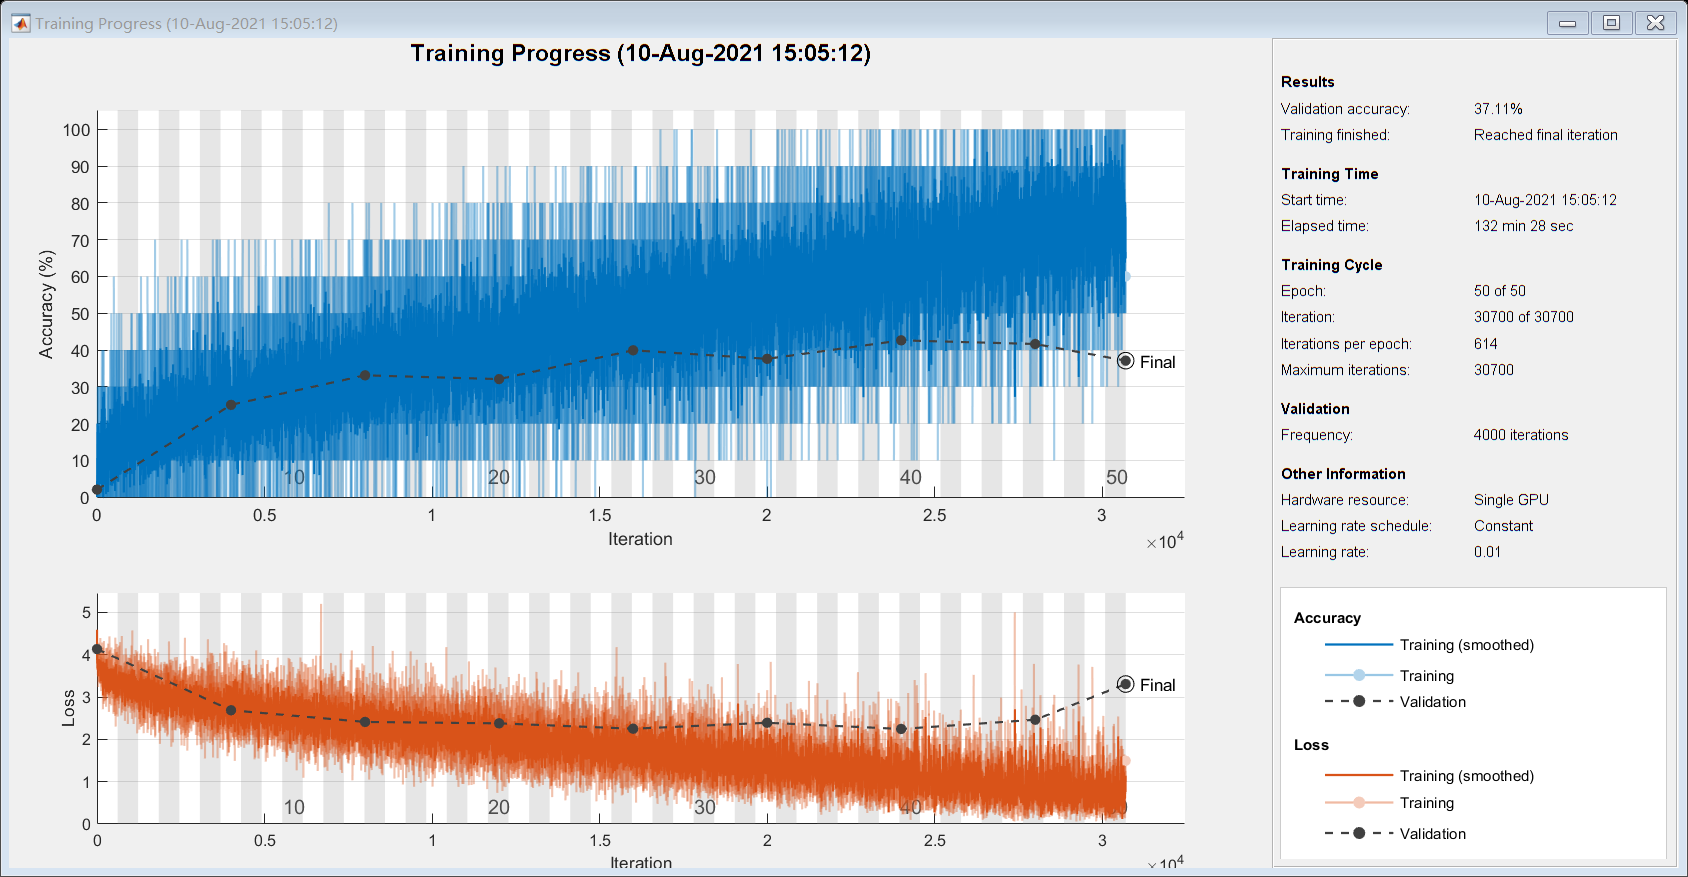

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


traininfo = struct with fields:
               TrainingLoss: [1×30700 double]
           TrainingAccuracy: [1×30700 double]
             ValidationLoss: [1×30700 double]
         ValidationAccuracy: [1×30700 double]
              BaseLearnRate: [1×30700 double]
        FinalValidationLoss: 3.3067
    FinalValidationAccuracy: 37.1103


[net, traininfo] = trainNetwork(resized_art_Train, lgraph, options)